%   Biometric Systems
%   CYS616
%   CONVOLUTIONAL NEURAL NETWORK FOR IRIS RECOGNITION
clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.
workspace;  % Make sure the workspace panel is showing.
reset(gpuDevice);  % Reset GPU memory
diary Progress.txt
diary on

## Load train Data

categories = {
'001','002','003','004','005','006','007','008','009','010', ...
'011','012','013','014','015','016','017','018','019','020', ...
'021','022','023','024','025','026','027','028','029','030', ...
'031','032','033','034','035','036','037','038','039','040', ...
'041','042','043','044','045','046','047','048','049','050', ...
'051','052','053','054','055','056','057','058','059','060', ...
'061','062','063','064','065','066','067','068','069','070', ...
'071','072','073','074','075','076','077','078','079','080', ...
'081','082','083','084','085','086','087','088','089','090', ...
'091','092','093','094','095','096','097','098','099','100', ...
'101','102','103','104','105','106','107','108','109','110', ...
'111','112','113','114','115','116','117','118','119','120', ...
'121','122','123','124','125','126','127','128','129','130', ...
'131','132','133','134','135','136','137','138','139','140', ...
'141','142','143','144','145','146','147','148','149','150', ...
'151','152','153','154','155','156','157','158','159','160', ...
'161','162','163','164','165','166','167','168','169','170', ...
'171','172','173','174','175','176','177','178','179','180', ...
'181','182','183','184','185','186','187','188','189','190', ...
'191','192','193','194','195','196','197','198','199','200', ...
'201','202','203','204','205','206','207','208','209','210', ...
'211','212','213','214','215','216','217','218','219','220', ...
'221','222','223'};

    imdsTrain = imageDatastore(fullfile(pwd,'Dataset/TrainData', categories),'IncludeSubfolders',true,'FileExtensions','.bmp','LabelSource','foldernames');
num_train = size(imdsTrain.Files,1);

## Size of first image in dataset

    img = readimage(imdsTrain,1);
    [x , y , z] = size(img);

## Load Test Data

    imdsValidation = imageDatastore(fullfile(pwd,'Dataset/TestData', categories),'IncludeSubfolders',true,'FileExtensions','.bmp','LabelSource','foldernames');
num_test = size(imdsValidation.Files,1);

## Calculate the number of images in each category.

    labelCount = countEachLabel(imdsTrain);

## Define Network Architecture

    layers = [
 
    imageInputLayer([x y z]);  
 
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer(); 
 
    maxPooling2dLayer(5,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer();
 
         averagePooling2dLayer(5,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer();
    
    maxPooling2dLayer(5,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer();
 
         averagePooling2dLayer(5,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer();
 
 
    fullyConnectedLayer(size(categories,2),'BiasLearnRateFactor',2);
    softmaxLayer
    classificationLayer];

## Specify Training Options

    options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',100, ...
    'Shuffle','every-epoch', ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 8, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.5, ...
    'LearnRateDropPeriod',50, ...
    'ExecutionEnvironment','gpu', ...
    'Plots','training-progress', ...
    'Verbose', true, 'VerboseFrequency', 10);

## Train Network Usin

## g Training Data

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:28 |        0.00% |        0.00% |       5.4170 |       5.8509 |          0.0010 |
|       1 |          10 |       00:00:32 |        0.00% |              |       5.3332 |              |          0.0010 |
|       1 |          20 |       00:00:33 |        0.00% |              |       5.8313 |              |          0.0010 |
|       1 |          30 |       00:00:34 |        0.00% |              |       5.6186 |              |          0.

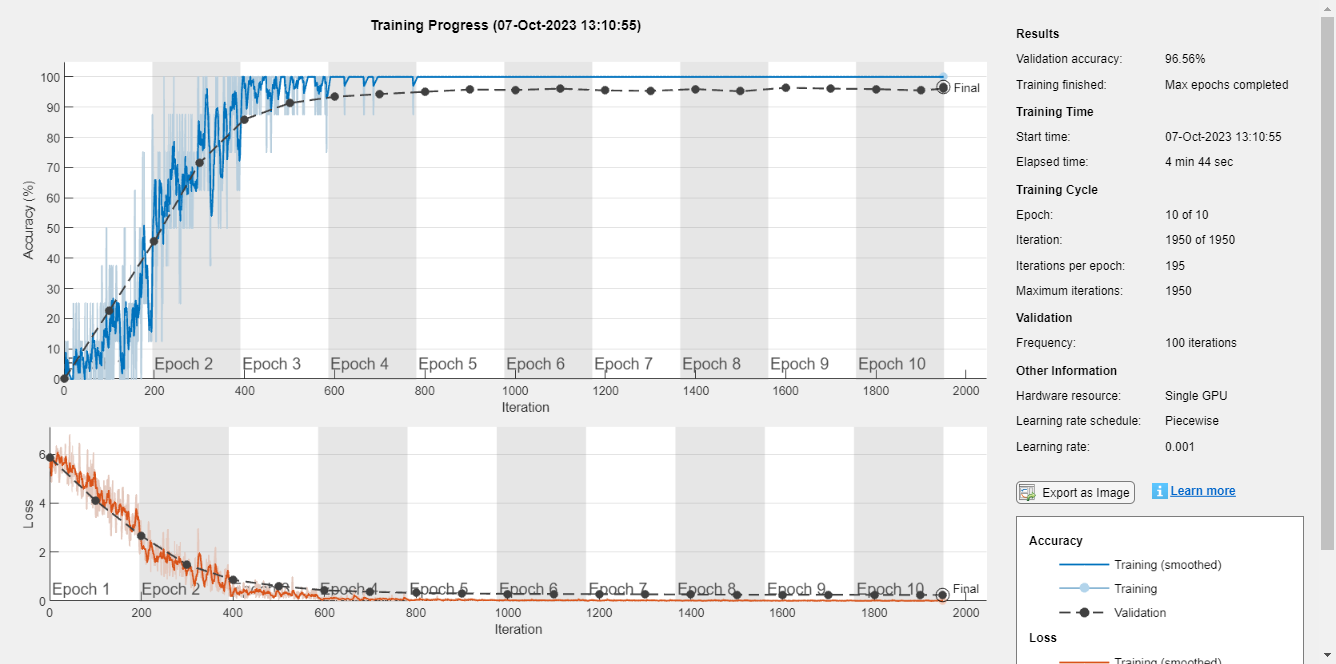

net_Wael =   SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


info = struct with fields:
               TrainingLoss: [5.4170 5.7746 5.5091 4.8763 5.9782 5.9439 5.8576 5.4470 5.7613 5.3332 5.8343 5.5465 5.2096 5.7684 6.3228 6.0448 6.2197 6.1310 5.7587 5.8313 4.8504 5.1201 5.8421 6.2170 6.2671 5.9091 5.2242 5.4300 5.8661 … ] (1×1950 double)
           TrainingAccuracy: [0 0 0 12.5000 0 0 0 12.5000 0 0 0 0 0 0 0 0 0 0 0 0 25 12.5000 0 0 0 0 25 0 0 0 0 0 25 0 0 12.5000 12.5000 12.5000 0 12.5000 0 0 0 0 0 0 25 0 12.5000 0 25 0 0 0 0 0 0 12.5000 25 0 12.5000 12.5000 12.5000 … ] (1×1950 double)
             ValidationLoss: [5.8509 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×1950 double)
         ValidationAccuracy: [0 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN N

    [net_Wael, info] = trainNetwork(imdsTrain,layers,options)

save('TrainedNetwork.mat','net_Wael')
movefile('TrainedNetwork.mat','results')

## Classify validation

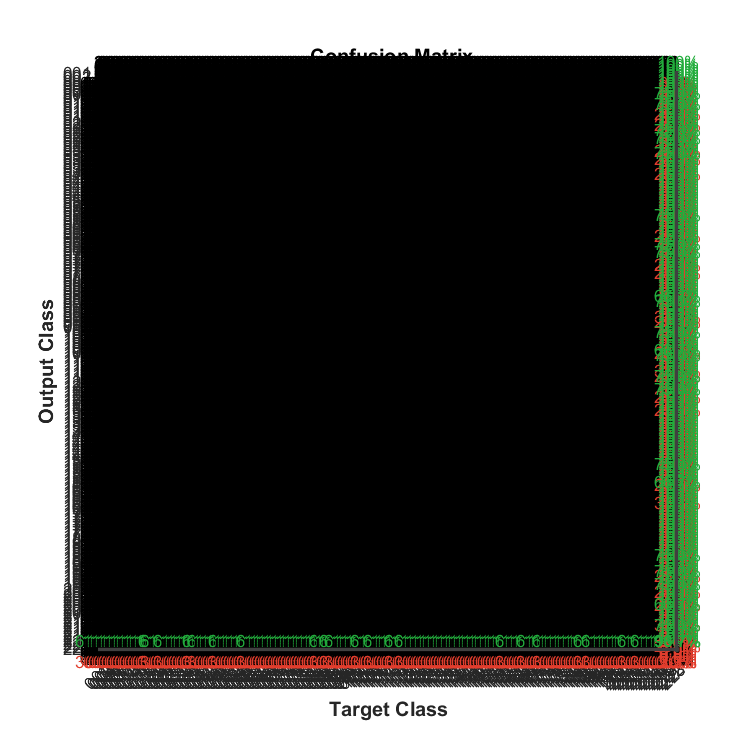

cn =   Figure (PLOTCONFUSION1) with properties:

      Number: 1
        Name: 'Confusion (plotconfusion)'
       Color: [1 1 1]
    Position: [468 132 600 600]
       Units: 'pixels'

  Show all properties


    labels = classify(net_Wael,imdsValidation);
    cn = plotconfusion(imdsValidation.Labels,labels)

## Compute Accuracy

    YValidation = imdsValidation.Labels;
    accuracy02 = sum(labels == YValidation)/numel(YValidation)*100;
    dis=['The final accuracy rate is: ', num2str(accuracy02,'%2.2f'), '%'];
    disp(dis);
diary off

## move diary file

movefile('Progress.txt','results')

## **Test one at a time**

true=0;
false=0;
    for i = 1:size(imdsValidation.Files,1)
            if labels(i) == imdsValidation.Labels(i)
               true=true+1;
            else
                false=false+1;  
            end
    end

## Find the square root of the false matches to determine the subplots

    f0=floor(sqrt(false));
    if f0 == sqrt(false)
        f1=f0;
    else
        f1=f0+1;
    end

## Recalbirating true and false

    true=0;
    false=0;

## start plotting mismatches

    falsefig = figure('Name','All Mismatch Pictures','Visible','off','Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

    for i = 1:size(imdsValidation.Files,1)
        imf = imread(imdsValidation.Files{i});
        if labels(i) ~= imdsValidation.Labels(i)
            
            colorText = 'r';
            false=false+1;  
            if false > f0*f1
                    break     
            else 
            subplot(f1,f0,false);
                                    imshow(imf);

            title(char(labels(i)),'Color',colorText);
            end
        end
    end
    
    xlabel('ALL mismatch incidents');
    saveas(falsefig,'All Mismatches.png');
    movefile('All Mismatches.png','results');

## start plotting sample of correct match

    truefig = figure('Name','Sample of Correct Match','Visible','off','Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
    
    true=0;
    false=0;
        for i = 1:size(imdsValidation.Files,1)
            ii = randi(size(imdsValidation.Files,1));
            imt = imread(imdsValidation.Files{ii});
            if labels(ii) == imdsValidation.Labels(ii)
               colorText = 'g'; 
               true=true+1;
               if true > f0*f1
                    break    
               else 
                       subplot(f1,f0,true);
                        imshow(imt);
                       title(char(labels(ii)),'Color',colorText);
               end
            end
        end
        xlabel('Sample of Correct Incidents');
        saveas(truefig,'Sample Matches.png');
        movefile('Sample Matches.png','results');